## MA 402 Project 1

### Friday March 11, 2022

### Andrea Stancescu, Jenna Varnell, Omry Bewster

% Andrea Stancescu, Jenna Varnell, Omry Brewster
% MA 402 Project 1 
% 3-11-2022
% MATLAB .mlx file with integrated text and code

### 1. Introduction

Chemical reactions can be simulated by equations that relate the changing quantities of the reaction. As the derivative of a function provides the rate at which that function is changing with respect to its independent variable, the equations describing these phenomena often involve one or more derivatives, and we refer to them as differential equations

The purpose of this project is to model the Michaelis-Menten system which is a model of an enzyme reaction. The four components of the enzyme reaction are an enzyme (E), a substrate (S), the enzyme-substrate compound (C), and the product of the reaction (P). 

The Michaelis-Menten system is represented below as:

#### 
$$E+S\underset{\theta_1 }{\overset{\theta_2 }{\iff} } C\overset{\theta_3 }{\longrightarrow} E+P$$


Throughout the project, we will assume that the reaction rates are proportional to the product of the concentrations of the reactions which will lead us to the following system of four differential equations:

#### $\begin{array}{l}
{\left\lbrack S\right\rbrack }^{\prime } \left(t\right)\;=-\theta_1 \left\lbrack E\right\rbrack \left\lbrack S\right\rbrack +\theta_2 \left\lbrack C\right\rbrack \\
{\left\lbrack E\right\rbrack }^{\prime } \left(t\right)=-\theta_1 \left\lbrack E\right\rbrack \left\lbrack S\right\rbrack +\left(\theta_2 +\theta_3 \right)\left\lbrack C\right\rbrack \\
{\left\lbrack C\right\rbrack }^{\prime } \left(t\right)={\;\theta }_1 \left\lbrack E\right\rbrack \left\lbrack S\right\rbrack -\left(\theta_2 +\theta_3 \right)\left\lbrack C\right\rbrack \\
{\left\lbrack P\right\rbrack }^{\prime } \left(t\right)=\theta_3 \left\lbrack C\right\rbrack \;\;
\end{array}$                                                                                                   (1)

Throughout the project we will also use $\theta_1$ to signify the forward reaction rate coefficient, $\theta_2 \;$to signify the reverse reaction rate coefficient, and $\theta_3$ to represent the catalytic reaction rate coefficient. Furthermore, we will also use the following initial values when solving the system of equations using differential methods and Euler's method:

####                                                                                                                              $\begin{array}{l}
S_0 =5*{10}^{-2\;} \;\frac{\mathrm{mol}}{L}\\
E_0 =2*{10}^{-2} \;\frac{\mathrm{mol}}{L}\\
C_0 =0\;\frac{\mathrm{mol}}{L}\\
P_0 =0\;\frac{\mathrm{mol}}{L}
\end{array}$                                                                                                                        (2)

We will be solving the system of differential equations using computational numerical ordinary differential equation solvers as well as Euler's Method. In Section 2, we use MATLAB's built in ode45() function to solve th system of first order differential equations over the time span of [0,30] and the initial values listed above. In Section 3, we use Euler's method with 3 different step sizes to approximate the solution to the initial value problem. In Sections 4 and 5 we repeat the methods used in Sections 2 and 3 respectively while sampling the reaction rates from lognormal distributions and additionally outputing an expected value and a confidence interval for the final product of the reaction, $\left\lbrack P\right\rbrack$. 

### 2 Differentiation Method 

Solutions to ordinary differential equations cannot be uniquely determined without some provided initial value. We are often given a first order equation of the following form with the corresponding initial value

$y{\;}^{\prime } \left(t\right)=f\left(t,y\left(t\right)\right)$    ;     $\left(0,y\left(0\right)\right)$  

Then from Taylor's Theorem we have that


$$y\left(x\right)=y\left(0\right)+y\prime \left(0\right)x+\frac{1}{2}y\prime \prime \left(0\right)x^2 +\frac{1}{6}y^{\left(3\right)} \left(0\right)x^3 +\dots$$


which we ultimately wish to solve for the respective coefficients. Thus, we will differentiate our given differential equation and plug in our initial value of $t=0$ to approximate the solution:


$$y\prime \prime \left(0\right)=\frac{\partial }{\partial t}f\left(0,y\left(0\right)\right)+\frac{\partial }{\partial y}f\left(0,y\left(0\right)\right)*y^{\prime } \left(0\right)$$


#### 2.1 Results

Since we are given the values of the reaction rate coefficients, $\theta_1 \;,\theta_{2\;} \;,\textrm{and}\;\theta_3$ , we can solve the initial value problem by setting up a system of four differential equations. Consequently, our anonymous function, ddt, takes in arguments t and x and returns the system given in (1).

The ode45() function in MATLAB takes in ddt, the 4x1 matrix of the system of four differential equations, tspan = [0,30] which represents the time interval over which we wish to model the chemical reaction, and the initial values as given in (2) which are passed in via a 4x1 vector.

The resulting outputted plot seen in figure 1 shows that the concentration of the enzyme (seen in dark blue) and the enzyme-substrate compound (seen in light blue) are inversely proportional to each other. The concentration of the enzyme reaches its peak around a time of t = 5 meanwhile, the concentration of the enzyme-substrate compound reaches its minimum at this time. Furthermore, the substrate the product concentrations are inversely proportional as seen by the red and green lines. This intuitively shows that the product is increasing as a result of the substrate decreasing which signifies the progression of the experiment.  

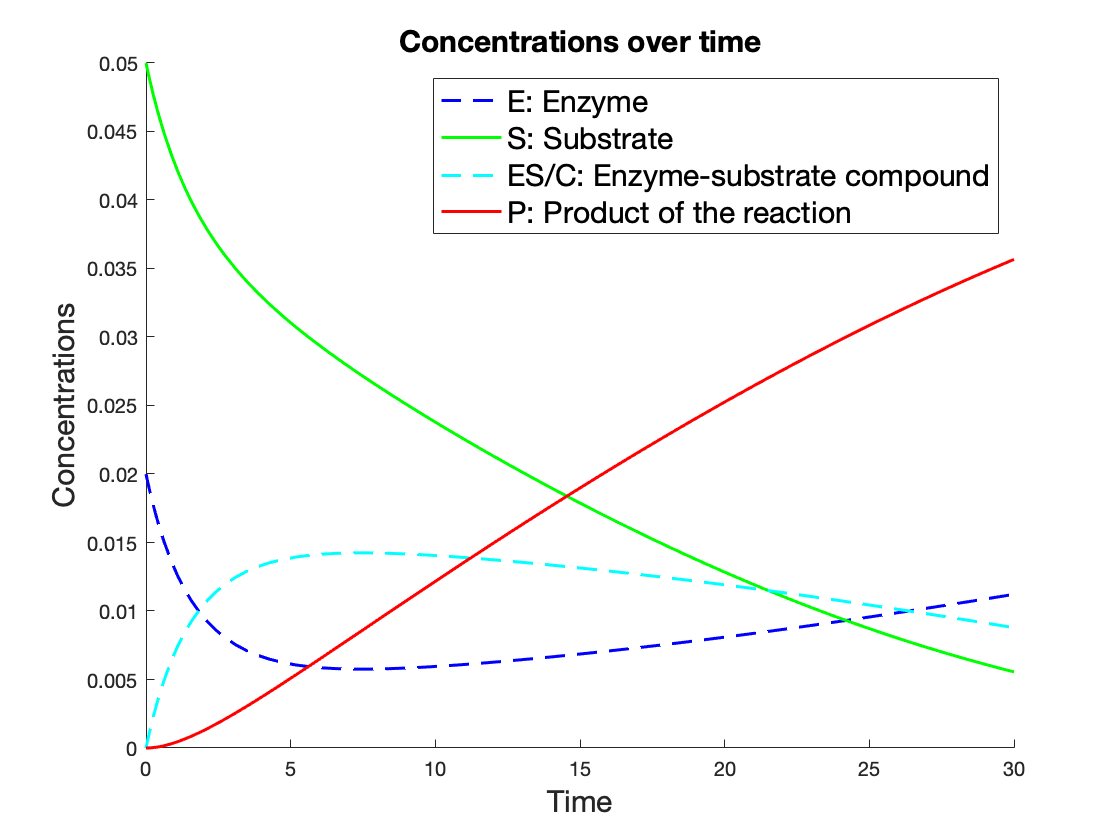


%% part a 

theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];


ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)];

[t, y] = ode45(ddt, [0 30], x0);

figure;
hold on 
plot(t, y(:,1), 'b--', 'LineWidth', 1.5)
plot(t, y(:,2), 'g', 'LineWidth', 1.5)
plot(t, y(:,3), 'c--', 'LineWidth', 1.5)
plot(t, y(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time','Fontsize',15)
xlabel('Time','FontSize', 15)
ylabel('Concentrations','FontSize',15)
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction','FontSize',15) 
hold off

                        Figure 1: The results of the reaction solved with integration methods 

### 3. Euler's Method

Numerical iteration and knowledge of slopes can be used to approximate the solution of an initial value problem. Suppose we are given a first order equation of the following form with the corresponding initial value

$y{\;}^{\prime } \left(t\right)=f\left(t,y\left(t\right)\right)$    ;     $\left(0,y\left(0\right)\right)$  

and suppose that we wish to approximate the solution near a value of $t=0$. Since we know the true value of $y\left(t\right)\;$at $t=0\;$ and we know the derivative at this point, we can use knowledge of calculus and the tangent line to write the following equation of the tangent line to the solution at $t=0$ :


$$y\left(t\right)=y\left(0\right)+y^{\prime } \left(0\right)*\left(t-0\right)$$


Given that our subsequent value of t is close enough to our prior value, we can be assured that our approximation is fairly close to the true value of the solution at t. We can continue this approximation as many times as needed to get approximations of the desired root. 

Often, we will assume that the step sizes between subsequent values of t are uniform and thus we can replace $\left(t-0\right)=h=\frac{\left(t_n -t_0 \right)}{n}$ where n is the number of step sizes. 

Intuitively, we expect that smaller step sizes (h) will lead to more accurate approximations and flatter functions, $y\left(t\right)$, will lead to better estimates due to the fact that our calculated derivatives will closely resemble the function itself. 

In Section 3, we use the outlined Euler's Method to approximate the solution of the system of differential equations for 3 step sizes of 0.1, 1, and 2.

#### 3.1 Results with a Step Size of 0.1

Using the same initial values and system of differential equations are in Section 2, we can approximate the solution we previously found using Euler's Method. 

After defining the anonymous function, ddt, with the system of four differential equations, we create a for loop to iterate over each subsequent value of t. In each iteration, we calculate the equation of the updated tangent line and then graph the soltions found over the time span of [0,30]. Although there are very slight differences in the curves, Figure 2 almost perfectly resembles Figure 1. 

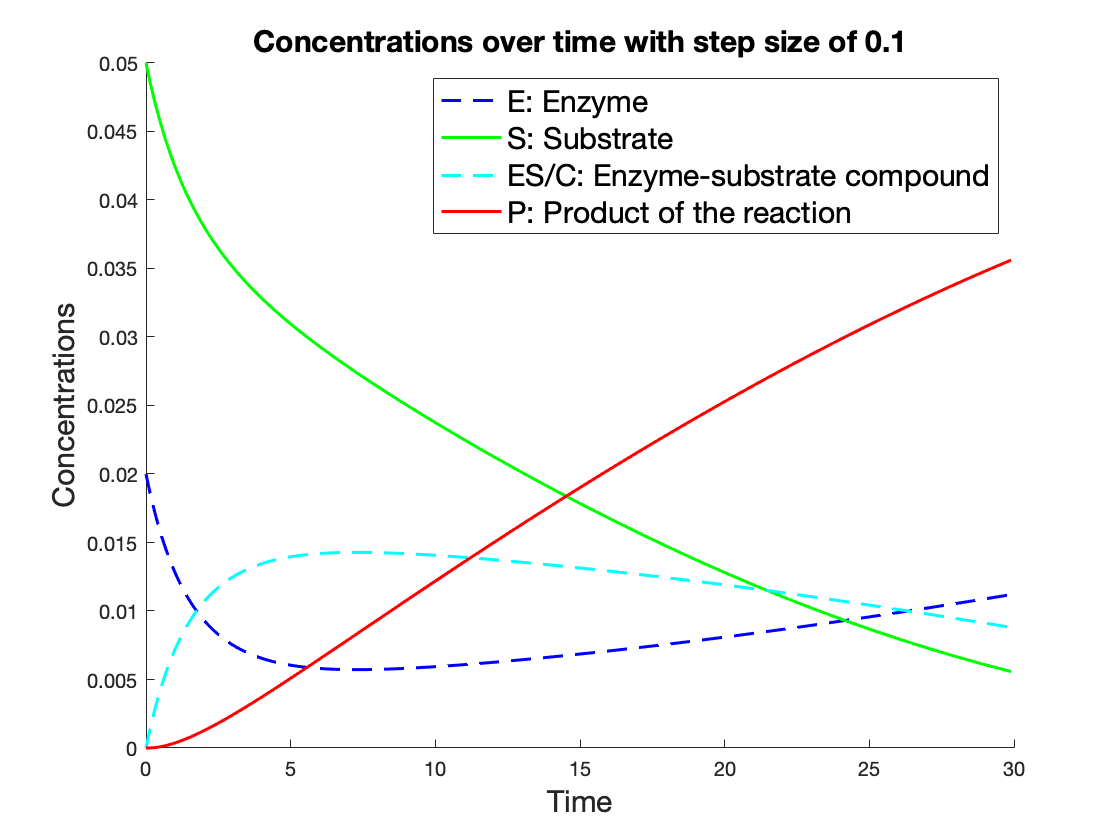


%% part b 
% step size h = 0.1
theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)]';

h1 = 0.1;
y1 = zeros((30/h1), 4);
y1(1, :) = x0';
for i=1:((30/h1) - 1)
   y1(i+1, :) =  y1(i,:) + h1 * (ddt(i*h1, y1(i,:)));
end

figure;
hold on 
plot(0:h1:30-h1, y1(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,2), 'g', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time with step size of 0.1','FontSize',15)
xlabel('Time','Fontsize',15)
ylabel('Concentrations','FontSize',15)
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction','FontSize',15)
hold off

                        Figure 2: The results of the reaction solved with Euler's Method (h = 0.1) 

#### 3.2 Results with a Step Size of 1

Below, we repeat the same steps as in 3.1 and simply replace the step size with 1 instead of 0.1. The comparison of Figure 3 with Figure 2 and Figure 1 shows a slighly more obvious difference as some of the lines become more abrupt and. This is due to the larger step size which decreases the accuracy in our approximation. 

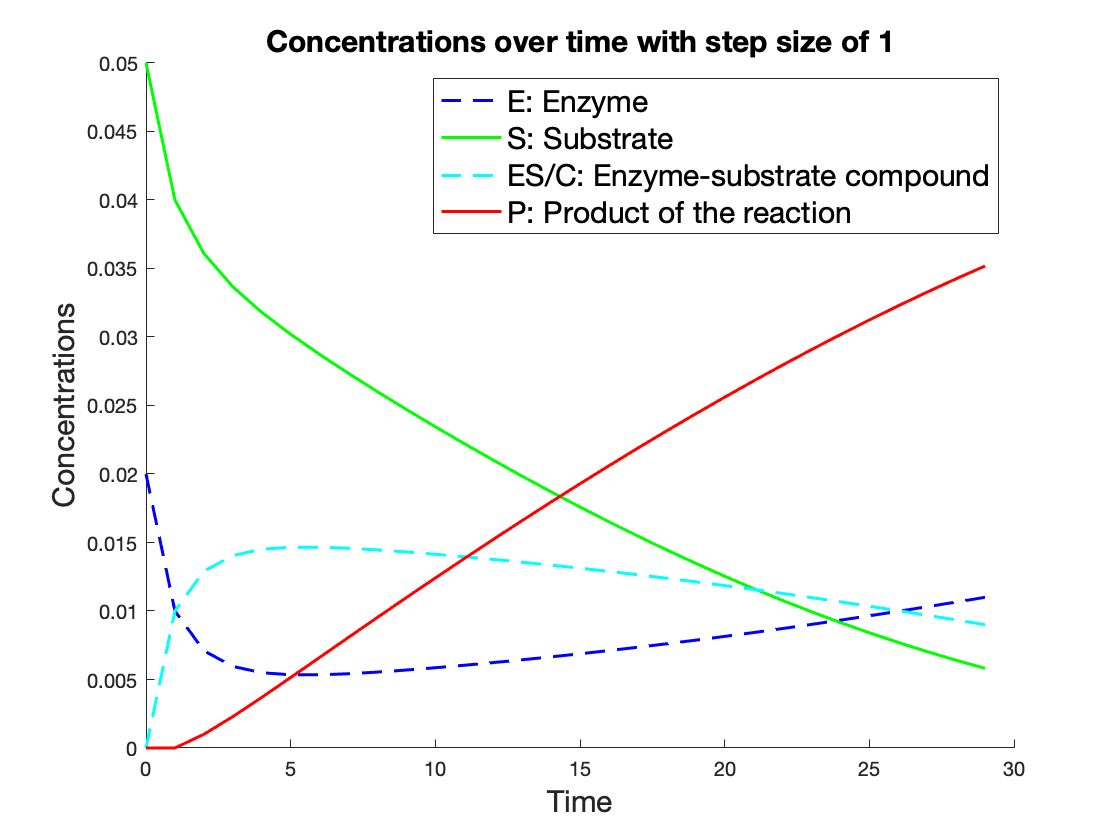

%% part b  
% step size h = 1
theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)]';

h2 = 1;
y2 = zeros((30/h2), 4);
y2(1, :) = x0';
for i=1:((30/h2) - 1)
   y2(i+1, :) =  y2(i,:) + h2 * (ddt(i*h2, y2(i,:)));
end

figure;
hold on 
plot(0:h2:30-h2, y2(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h2:30-h2, y2(:,2), 'g', 'LineWidth', 1.5)
plot(0:h2:30-h2, y2(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h2:30-h2, y2(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time with step size of 1','FontSize',15)
xlabel('Time','FontSize',15)
ylabel('Concentrations','FontSize',15)
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction','FontSize',15)
hold off

                        Figure 3: The results of the reaction solved with Euler's Method (h = 1) 

#### 3.3 Results with a Step Size of 2

Below, we repeat the same steps as in 3.1 and 3.2 and simply replace the step size with 2. 

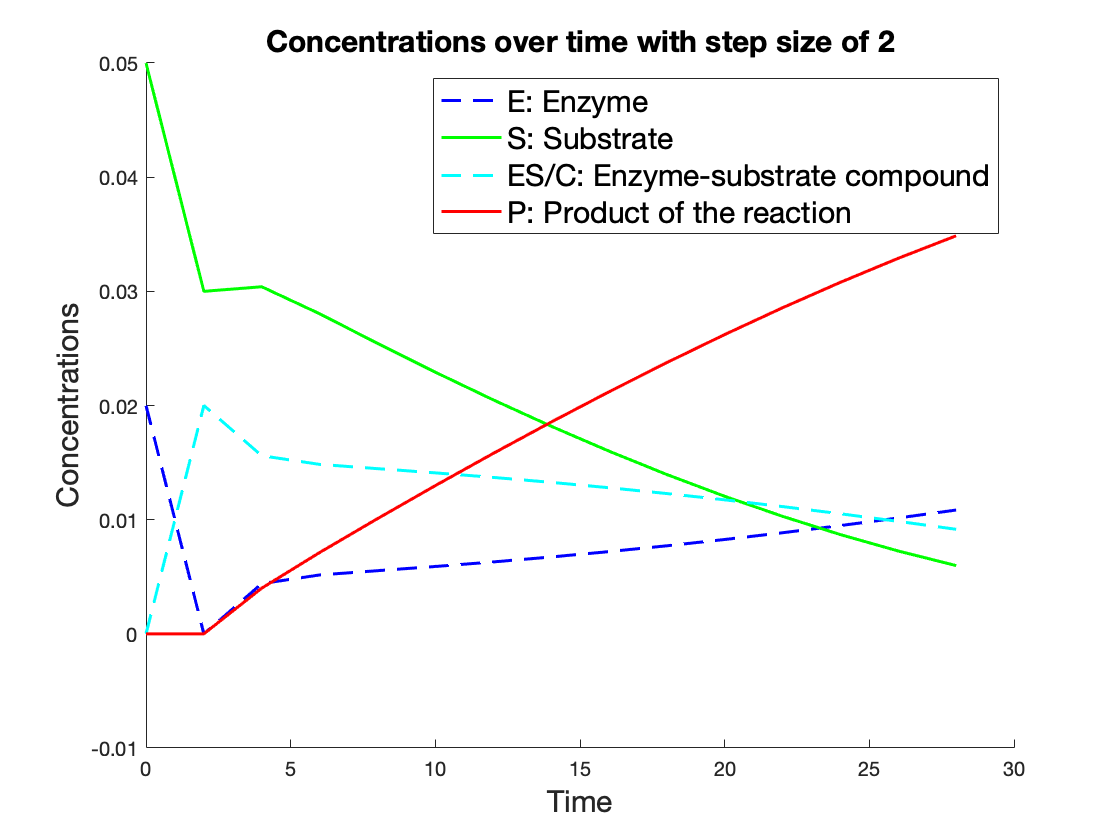

%% part b 
% step size h = 2

theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)]';

h3 = 2;
y3 = zeros((30/h3), 4);
y3(1, :) = x0';
for i=1:((30/h3) - 1)
   y3(i+1, :) =  y3(i,:) + h3 * (ddt(i*h3, y3(i,:)));
end

figure;
hold on 
plot(0:h3:30-h3, y3(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h3:30-h3, y3(:,2), 'g', 'LineWidth', 1.5)
plot(0:h3:30-h3, y3(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h3:30-h3, y3(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time with step size of 2','FontSize',15)
xlabel('Time','FontSize',15)
ylabel('Concentrations','FontSize',15)
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction','FontSize',15)
hold off

#### 3.4 All Four Graphs Compared

Next, we have compiled all four graph into one subplot in order to easily compare them. The comparison of Figure 4 with Figures 1, 2 and 3 shows an apparent difference as the plots of the lines are no longer smooth. Rather they display sharp changes for smaller values of the time and they eventually become smoother as the time approaches 30. This is due to the much larger step size which causes the tangent line to be further from the true value of the root. However, as the number of iterations of Euler's method increases, our approximation converges to the true value of the solution which results in the smoother plots of the concentration amount. Differences between Figures 1,2, and 3 are harder to spot. If you look closely at Figure 3 with a step size of 1, you can see some sharp turns instead of curved edges. These are not as obvious as the sharp turns in Figure 4, but they are caused by the same reasons. Between Figure 1 and 2 there are no visible differences in the graphs. This is showing how accurate Euler's method can be with a small step size. 

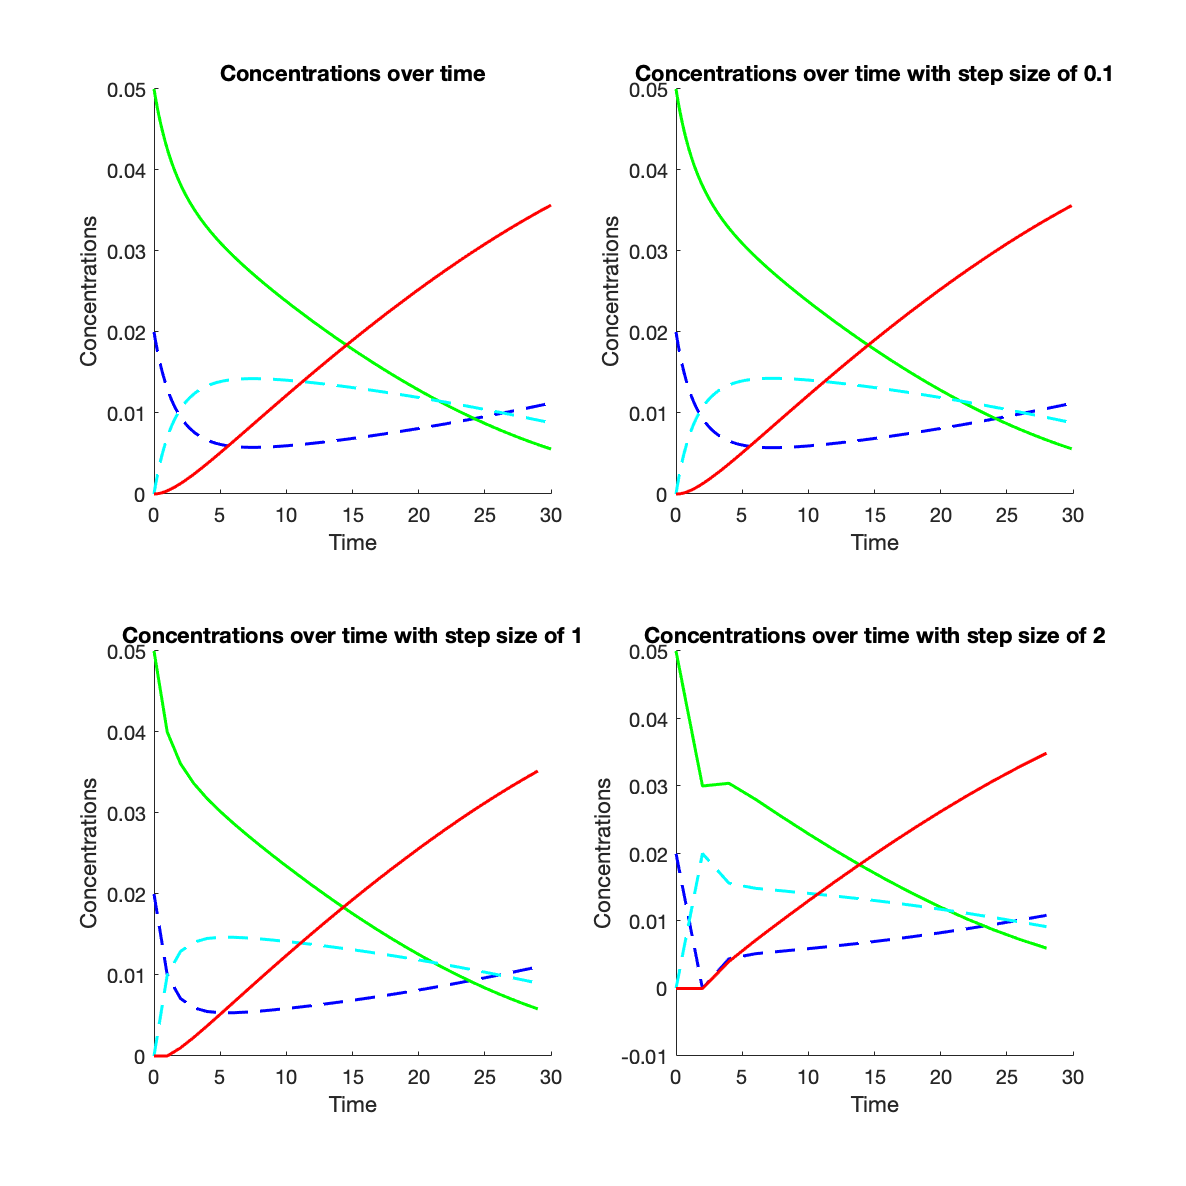

figure1=figure('Position', [1000, 1000, 1000, 1000]);
subplot(2,2,1);
hold on 
plot(t, y(:,1), 'b--', 'LineWidth', 1.5)
plot(t, y(:,2), 'g', 'LineWidth', 1.5)
plot(t, y(:,3), 'c--', 'LineWidth', 1.5)
plot(t, y(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time')
xlabel('Time')
ylabel('Concentrations')
%legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

subplot(2,2,2);
hold on 
plot(0:h1:30-h1, y1(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,2), 'g', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time with step size of 0.1')
xlabel('Time')
ylabel('Concentrations')
%legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction')
hold off

subplot(2,2,3);
hold on 
plot(0:h2:30-h2, y2(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h2:30-h2, y2(:,2), 'g', 'LineWidth', 1.5)
plot(0:h2:30-h2, y2(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h2:30-h2, y2(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time with step size of 1')
xlabel('Time')
ylabel('Concentrations')
%legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction')
hold off

subplot(2,2,4);
hold on 
plot(0:h3:30-h3, y3(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h3:30-h3, y3(:,2), 'g', 'LineWidth', 1.5)
plot(0:h3:30-h3, y3(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h3:30-h3, y3(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time with step size of 2')
xlabel('Time')
ylabel('Concentrations')

% fig = gcf;
% fig.Position(3) = fig.Position(3) + 400;
hold off

### 4. Differentiation Method with Lognormal Reaction Rate Coefficients

We will now repeat the methods described above where the reaction rate coefficients can be modeled by the random variables:

#### 
$$\begin{array}{l}
\theta_1 \sim \textrm{Lognormal}\left(2\ldotp 3,0\ldotp 09\right)\\
\theta_2 \sim \textrm{Lognormal}\left(-4,1\right)\\
\theta_3 \sim \textrm{Lognormal}\left(-2,0\ldotp 09\right)
\end{array}$$
 

where a lognormal random variable with mean ($\mu$ ) and variance ($\sigma^2$ ) can be modeled by:

####    
$$e^{\mu +\sigma Z}$$


where Z is assumed to be the standard normal random variable. 

#### 4.1 Results of 50 trials 

Below, we repeat the method performed in Section 2 with MATLAB's ode45() function for a sequence of 50 trials. We overlayed the plots of all 50 trials on Figure 5 which shows that the vast majority of the plots closely resembel figure 1, however, for some randomly chosen standard normal values, the concentrations deviate from the expected concentration. Furthermore, given a randomly chosen starting value of Z, if Z assumes a extreme value then the error in the concentration augments and amplifies as the time increases. 

This is clearly seen by the few lines for each component which begin to increasingly diverge as the time approaches 30. 

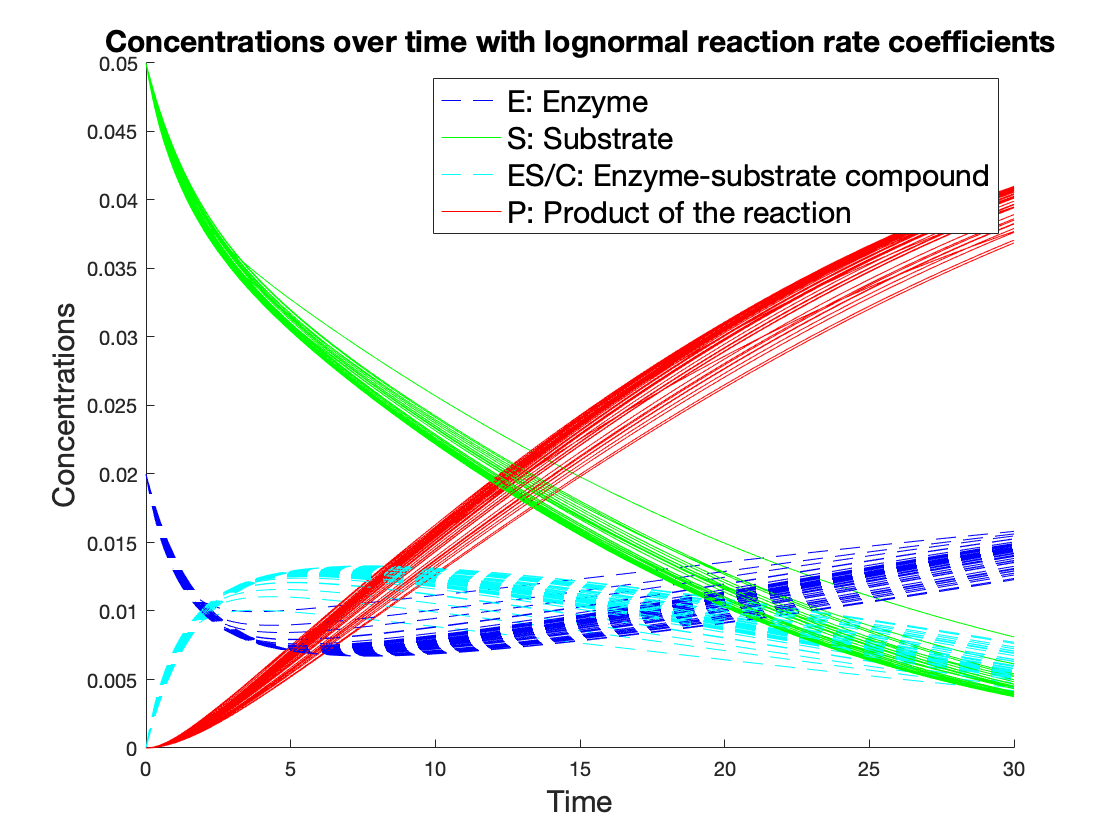


%% part c

e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.09*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.09*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    [t, y] = ode45(ddt, [0 30], x0);

    plot(t, y(:,1), 'b--')
    plot(t, y(:,2), 'g')
    plot(t, y(:,3), 'c--')
    plot(t, y(:,4), 'r')
end 

title('Concentrations over time with lognormal reaction rate coefficients','FontSize',15)
xlabel('Time','FontSize',15)
ylabel('Concentrations','FontSize',15)
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction','FontSize',15) 
hold off

                        Figure 5: The results of the reaction solved with integration method

                                                and lognormal reaction rate coefficients 

#### 4.2 Estimated Final Product Concentration 



%% part d

e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.09*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.09*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    [t, y] = ode45(ddt, [0 30], x0);

    lastproduct(i) = y(end,4);
end 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0008 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [-0.0008 , 0.0024] 


### 5. Euler's Method with Lognormal Reaction Rate Coefficients 

#### 5.1 Results with a Step Size of 2

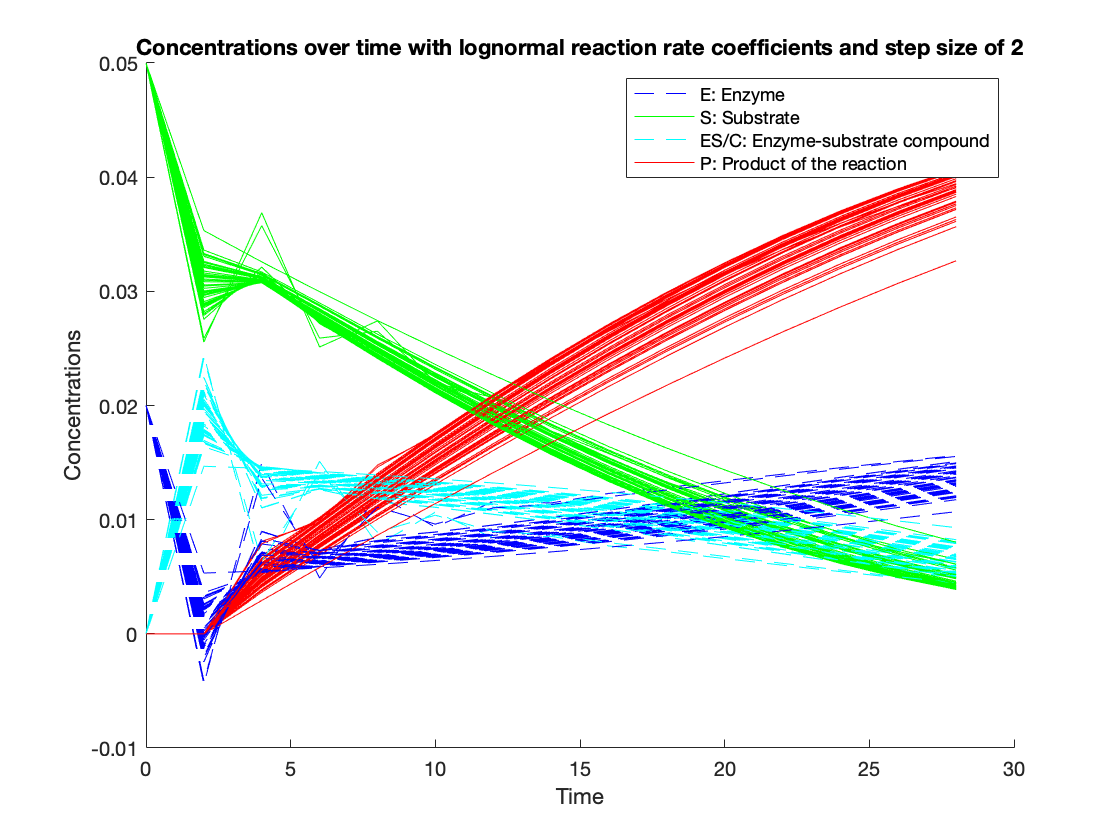

%% part e

% step size h = 2
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.09*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.09*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    
    h = 2;
    y = zeros((30/h), 4);
    y(1, :) = x0';
    for i=1:((30/h) - 1)
        y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:))');
    end

 
    lastproduct(i) = y(end,4);
    
    plot(0:h:30-h, y(:,1), 'b--')
    plot(0:h:30-h, y(:,2), 'g')
    plot(0:h:30-h, y(:,3), 'c--')
    plot(0:h:30-h, y(:,4), 'r')
end 

title('Concentrations over time with lognormal reaction rate coefficients and step size of 2')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

#### Estimated Final Product Concentration 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0008 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [-0.0008 , 0.0024] 


#### 5.2 Results with a Step Size of 1

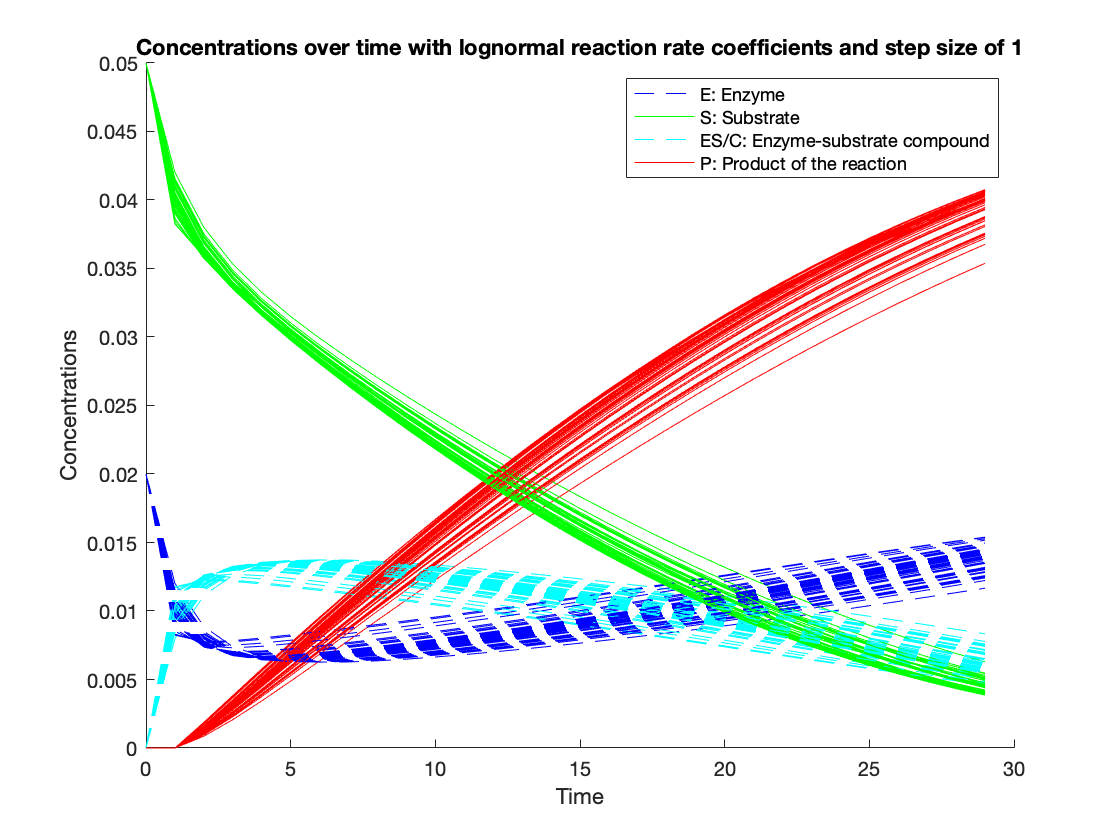

%% part e

% step size h = 1
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.09*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.09*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    
    h = 1;
    y = zeros((30/h), 4);
    y(1, :) = x0';
    for i=1:((30/h) - 1)
        y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:))');
    end

 
    lastproduct(i) = y(end,4);
    
    plot(0:h:30-h, y(:,1), 'b--')
    plot(0:h:30-h, y(:,2), 'g')
    plot(0:h:30-h, y(:,3), 'c--')
    plot(0:h:30-h, y(:,4), 'r')
end 

title('Concentrations over time with lognormal reaction rate coefficients and step size of 1')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

#### Estimated Final Product Concentration 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0008 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [-0.0007 , 0.0023] 


#### 5.2 Results with a Step Size of 0.1

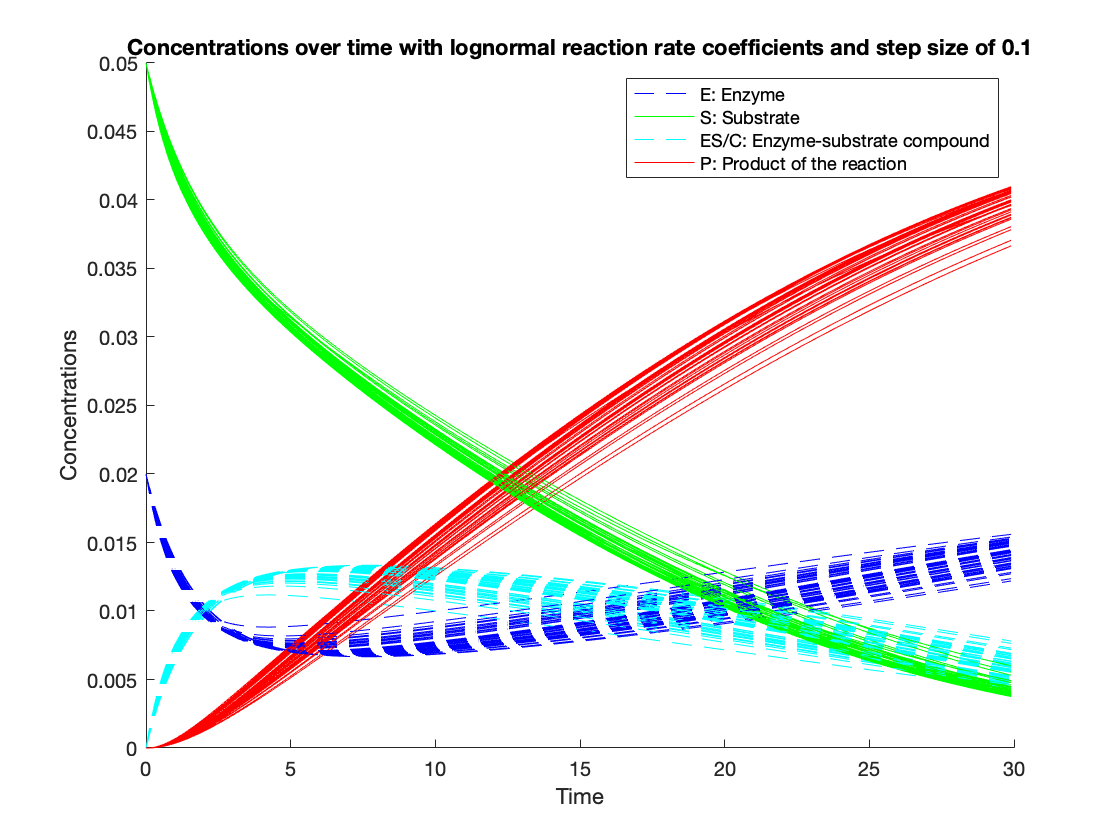

%% part e

% step size h = 0.1
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.09*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.09*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    
    h = 0.1;
    y = zeros((30/h), 4);
    y(1, :) = x0';
    for i=1:((30/h) - 1)
        y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:))');
    end

 
    lastproduct(i) = y(end,4);
    
    plot(0:h:30-h, y(:,1), 'b--')
    plot(0:h:30-h, y(:,2), 'g')
    plot(0:h:30-h, y(:,3), 'c--')
    plot(0:h:30-h, y(:,4), 'r')
end 

title('Concentrations over time with lognormal reaction rate coefficients and step size of 0.1')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

#### Estimated Final Product Concentration 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0001 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [-0.0005 , 0.0008] 
